# Assignment 11

# **Extended Kalman filter for navigation and tracking** 

By 

Group 19 

Ahmed Baza, Skoltech, 2020

Ahmed Elgohary, Skoltech, 2020

Mohammed Sayed, Skoltech, 2020

Ziad Baraka, Skoltech, 2020

**1. Generate a true trajectory *****X***** of an object that moves uniformly. Trajectory is deterministic, as no random disturbance affect a motion.**

**2. Generate also true values of range **D** and azimuth **$\beta$**. Plot generated motion in polar coordinate system.**

close all;
clear;

m = 1;    % Extrapolation steps
N = 26;   % Size of trajectory
NE = N-m; % Number of points for the extrapolation error

X = zeros(1,N);           % X-position
Y = zeros(1,N);           % Y-position
Vx = zeros(1,N);           % X-position
Vy = zeros(1,N);           % Y-position

X(1) = 1000;  % X initial value
Y(1) = 1000;  % Y initial value
Vx(1) = 10;      % X velocity initial value
Vy(1) = 10;      % Y velocity initial value
T = 1;        % Time step

D = zeros(1,N);             % Range
beta = zeros(1,N);          % Azimuth
D(1) = sqrt(X(1)^2+Y(1)^2); % Range initial value
beta(1) = atan2(X(1),Y(1));  % Azimuth initial value
    
sigma_x = 0.3;               % X position measurements noise standard deviation
sigma_y = 0.3;               % Y position measurements noise standard deviation
sigma_d = 50;               % Range measurements noise standard deviation
sigma_beta = 0.004;          % Azimuth measurements noise standard deviation

D_m = zeros(1,N);             % Range
beta_m = zeros(1,N);          % Azimuth
D_m(1) = D(1)+normrnd(0,sqrt(sigma_d));                      % Range measurements initialization
beta_m(1) = beta(1)+normrnd(0,sqrt(sigma_beta));              % Azimuth measurements initialization

% Vectors generation
for i = 2:N
    ax = normrnd(0,sqrt(sigma_x));
    ay = normrnd(0,sqrt(sigma_y));
    
    X(i) = X(i-1)+Vx(i-1)*T+ax*0.5*T^2;              % X vector generation
    Y(i) = Y(i-1)+Vy(i-1)*T+ay*0.5*T^2;              % Y vector generation
    Vx(i) = Vx(i-1) + ax*T;                         % Vx vector genetation
    Vy(i) = Vy(i-1) + ay*T;                         % Vy vector genetation

    D(i) = sqrt(X(i)^2+Y(i)^2);      % Range vector generation
    beta(i) = atan2(X(i),Y(i));      % Azimuth vector generation
    
    D_m(i) = D(i)+normrnd(0,sqrt(sigma_d));            % Range measurements vector generation
    beta_m(i) = beta(i)+normrnd(0,sqrt(sigma_beta));   % Azimuth measurements vector generation
end


**4. Transform polar coordinates **$D^m$** and **$\beta^m$** to Cartesian ones and get pseudo-measurements of coordinates** $x$** and **$y$**.**

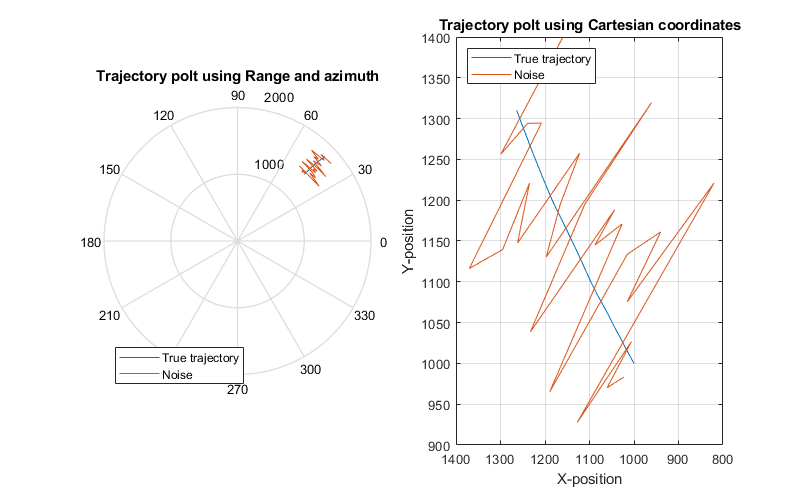

    X_m = D_m.*sin(beta_m);       % X measurements vector generation    
    Y_m = D_m.*cos(beta_m);       % Y measurements vector generation
    % Create the measurement vector  from pseudo-measurements of coordinates  and .
    %Z = [X_m;Y_m];                % Cartesian measurments
    Z = [D_m;beta_m];
    
% Trajectory plotting for visualization
figure
subplot(1,2,1)
polar(beta,D); hold on
polar(beta_m,D)
title('Trajectory polt using Range and azimuth')
legend({'True trajectory', 'Noise'},'location','southwest')

subplot(1,2,2)
plot(X,Y); set(gca, 'XDir','reverse'); hold on
plot(X_m,Y_m); set(gca, 'XDir','reverse')

title('Trajectory polt using Cartesian coordinates')
xlabel('X-position')
ylabel('Y-position')
legend({'True trajectory','Noise'},'location','northwest')
grid on
set(gcf,'position',[0,0,800,500]);

**5. Create the transition matrix **$\Phi$.

% state space matrices
phi = [1 T 0 0;0 1 0 0;0 0 1 T;0 0 0 1];

**6. Calculate state noise covariance matrix Q**

G = [0.5*T^2 0 ;T 0 ;0 0.5*T^2;0 T];      % input matrix, that determines how random acceleration affects state vector
Q = G*G'*sigma_x^2;           % covariance matrix of state noise

**7. Create the measurement error covariance matrix R needed for Kalman filter algorithm.**

% Initial measurement error covariance matrix
R = [sigma_d^2 0; 0 sigma_beta^2];

**8. Initial conditions for Kalman filter algorithm.**

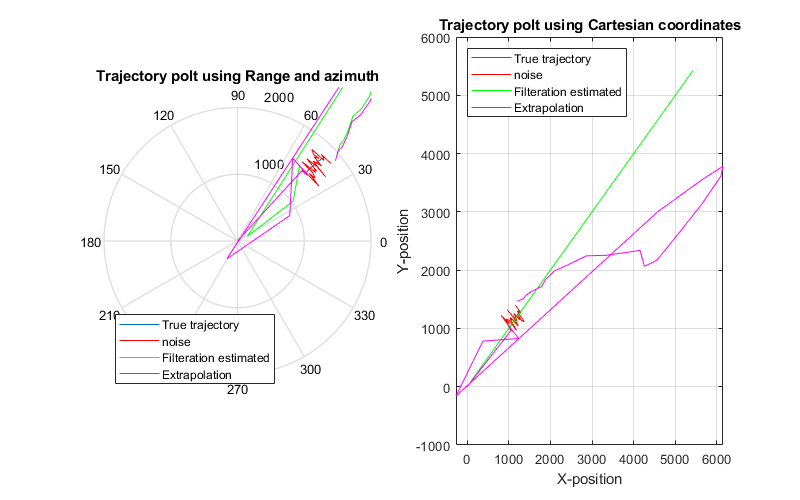

Xi = [D_m(1)*sin(beta_m(1));0;D_m(1)*cos(beta_m(1));0];   % State vector
P = (10^10)*eye(4);           % P matrix
XY = Xi(1)^2 + Xi(3)^2;
h = [sqrt(XY); atan2(Xi(1),Xi(3))];
dh_dx = [Xi(1)/sqrt(XY) 0 Xi(3)/sqrt(XY) 0; Xi(3)/(XY) 0 -Xi(1)/(XY) 0];

K = P*dh_dx'/(dh_dx*P*dh_dx'+R);   % Kalman gain initialization


xiE = zeros(N,1);      % Extrapolated X
yiE = zeros(N,1);      % Extrapolated Y
xi = zeros(N,1);       % filtered X
yi = zeros(N,1);       % filtered Y
Di = zeros(N,1);       % filtered Range
betai = zeros(N,1);    % filtered Azimuth
DiE = zeros(N,1);      % Extrapolated Range
betaiE = zeros(N,1);   % Extrapolated Azimuth
Ki = zeros(1,N);       % array of K(1,1)

%Ki(1) = K(1,1);
xi(1) = Xi(1);
yi(1) = Xi(3);

m=1;                   % extrapolation step
% Kalman filter
for i = 2:N
    
    % prediction
    Xi = phi*Xi;
    P = phi*P*phi'+Q;
    
    % filteration
    XY = Xi(1)^2 + Xi(3)^2;
    h = [sqrt(XY); atan2(Xi(1),Xi(3))];
    dh_dx = [Xi(1)/sqrt(XY) 0 Xi(3)/sqrt(XY) 0; Xi(3)/(XY) 0 -Xi(1)/(XY) 0];
    Xi = Xi+K*(Z(:,i)-h);   
    K = P*dh_dx'/(dh_dx*P*dh_dx'+R);
    P = (eye(4)-K*dh_dx)*P;
    
    Ki(i) = K(1,1);
    xi(i) = Xi(1);
    yi(i) = Xi(1);
    
    % extrapolation  
    if i >= m
        XiE = phi*Xi;     % Extrapolated state vector
    end
    
    % Extrapolated X,Y
    xiE(i) = XiE(1);
    yiE(i) = XiE(3);
    
    % Range and azimuth estimation (filtered and extrapolated)
    Di(i) = sqrt(Xi(1)^2+Xi(3)^2);
    betai(i) = atan2(Xi(1),Xi(3));
    DiE(i) = sqrt(XiE(1)^2+XiE(3)^2);
    betaiE(i) = atan2(XiE(1),XiE(3));
    
end
% Trajectory plotting for visualization
figure
subplot(1,2,1)
polar(beta,D)
hold on
polar(beta_m,D_m,'r')
polar(betai,Di,'g')
polar(betaiE,DiE,'m')
title('Trajectory polt using Range and azimuth')
legend({'True trajectory','noise','Filteration estimated','Extrapolation'},'location','southwest')

subplot(1,2,2)
plot(X,Y)
hold on
plot(X_m,Y_m,'r')
plot(xi,yi,'g')
plot(xiE,yiE,'m')
title('Trajectory polt using Cartesian coordinates')
xlabel('X-position')
ylabel('Y-position')
legend({'True trajectory','noise','Filteration estimated','Extrapolation'},'location','northwest')
grid on
set(gcf,'position',[0,0,800,500]);

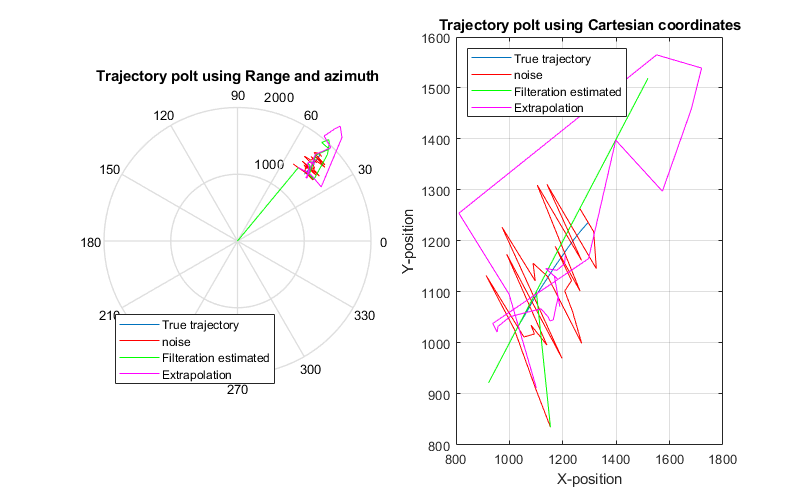

% Kalman errors initialization

Errx = zeros(500,N);          % X true estimation error
ErrxE = zeros(500,NE);        % X-extrapolated true estimation error
Erry = zeros(500,N);          % Y true estimation error
ErryE = zeros(500,NE);        % Y-extrapolated true estimation error
ErrD = zeros(500,N);          % D true estimation error
ErrDE = zeros(500,NE);        % D-extrapolated true estimation error
Errbeta = zeros(500,N);       % beta true estimation error
ErrbetaE = zeros(500,NE);     % beta-extrapolated true estimation error
K500 = zeros(500,N);           % kalman filter gain matrix

for M = 1:500
    
    X = zeros(1,N);           % X-position
    Y = zeros(1,N);           % Y-position
    Vx = zeros(1,N);           % X-position
    Vy = zeros(1,N);           % Y-position
    
    X(1) = 1000;  % X initial value
    Y(1) = 1000;  % Y initial value
    Vx(1) = 10;      % X velocity initial value
    Vy(1) = 10;      % Y velocity initial value
    
    D = zeros(1,N);             % Range
    beta = zeros(1,N);          % Azimuth
    D(1) = sqrt(X(1)^2+Y(1)^2); % Range initial value
    beta(1) = atan2(X(1),Y(1));  % Azimuth initial value
    
    D_m = zeros(1,N);             % Range
    beta_m = zeros(1,N);          % Azimuth
    D_m(1) = D(1)+normrnd(0,sqrt(sigma_d));                      % Range measurements initialization
    beta_m(1) = beta(1)+normrnd(0,sqrt(sigma_beta));              % Azimuth measurements initialization
    
    % Vectors generation
    for i = 2:N
        ax = normrnd(0,sqrt(sigma_x));
        ay = normrnd(0,sqrt(sigma_y));
        
        X(i) = X(i-1)+Vx(i-1)*T+ax*0.5*T^2;              % X vector generation
        Y(i) = Y(i-1)+Vy(i-1)*T+ay*0.5*T^2;              % Y vector generation
        Vx(i) = Vx(i-1) + ax*T;                         % Vx vector genetation
        Vy(i) = Vy(i-1) + ay*T;                         % Vy vector genetation
    
        D(i) = sqrt(X(i)^2+Y(i)^2);      % Range vector generation
        beta(i) = atan2(X(i),Y(i));      % Azimuth vector generation
        
        D_m(i) = D(i)+normrnd(0,sqrt(sigma_d));            % Range measurements vector generation
        beta_m(i) = beta(i)+normrnd(0,sqrt(sigma_beta));   % Azimuth measurements vector generation
    end
    
        X_m = D_m.*sin(beta_m);       % X measurements vector generation    
        Y_m = D_m.*cos(beta_m);       % Y measurements vector generation
        % Create the measurement vector  from pseudo-measurements of coordinates  and .
        %Z = [X_m;Y_m];                % Cartesian measurments
        Z = [D_m;beta_m];
        
    % state space matrices
    phi = [1 T 0 0;0 1 0 0;0 0 1 T;0 0 0 1];
    G = [0.5*T^2 0 ;T 0 ;0 0.5*T^2;0 T];      % input matrix, that determines how random acceleration affects state vector
    Q = G*G'*sigma_x^2;           % covariance matrix of state noise
    % Initial measurement error covariance matrix
    R = [sigma_d^2 0; 0 sigma_beta^2];
    Xi = [D_m(1)*sin(beta_m(1));0;D_m(1)*cos(beta_m(1));0];   % State vector
    P = (10^10)*eye(4);           % P matrix
    XY = Xi(1)^2 + Xi(3)^2;
    h = [sqrt(XY); atan2(Xi(1),Xi(3))];
    dh_dx = [Xi(1)/sqrt(XY) 0 Xi(3)/sqrt(XY) 0; Xi(3)/(XY) 0 -Xi(1)/(XY) 0];
    
    K = P*dh_dx'/(dh_dx*P*dh_dx'+R);   % Kalman gain initialization
    
    xiE = zeros(N,1);      % Extrapolated X
    yiE = zeros(N,1);      % Extrapolated Y
    xi = zeros(N,1);       % filtered X
    yi = zeros(N,1);       % filtered Y
    Di = zeros(N,1);       % filtered Range
    betai = zeros(N,1);    % filtered Azimuth
    DiE = zeros(N,1);      % Extrapolated Range
    betaiE = zeros(N,1);   % Extrapolated Azimuth
    Ki = zeros(1,N);       % array of K(1,1)
    Px = zeros(N,1);       % X Calculation error initialization
    Py = zeros(N,1);       % Y Calculation error initialization
    
    %Ki(1) = K(1,1);
    xi(1) = Xi(1);
    yi(1) = Xi(3);
    
    m=1;                   % extrapolation step
    % Kalman filter
    for i = 2:N
        
        % prediction
        Xi = phi*Xi;
        P = phi*P*phi'+Q;
        
        % filteration
        XY = Xi(1)^2 + Xi(3)^2;
        h = [sqrt(XY); atan2(Xi(1),Xi(3))];
        dh_dx = [Xi(1)/sqrt(XY) 0 Xi(3)/sqrt(XY) 0; Xi(3)/(XY) 0 -Xi(1)/(XY) 0];
        Xi = Xi+K*(Z(:,i)-h);   
        K = P*dh_dx'/(dh_dx*P*dh_dx'+R);
        P = (eye(4)-K*dh_dx)*P;
        
        Ki(i) = K(1,1);
        xi(i) = Xi(1);
        yi(i) = Xi(1);
        
        % extrapolation  
        if i >= m
            XiE = phi*Xi;     % Extrapolated state vector
        end
        
        % Extrapolated X,Y
        xiE(i) = XiE(1);
        yiE(i) = XiE(3);
        
        % Range and azimuth estimation (filtered and extrapolated)
        Di(i) = sqrt(Xi(1)^2+Xi(3)^2);
        betai(i) = atan2(Xi(1),Xi(3));
        DiE(i) = sqrt(XiE(1)^2+XiE(3)^2);
        betaiE(i) = atan2(XiE(1),XiE(3));
        
        % True estimation error calculation
        Errx(M,i) = (Xi(1)-X(i))^2;
        Erry(M,i) = (Xi(3)-Y(i))^2;
        ErrD(M,i) = (Di(i)-D(i))^2;
        Errbeta(M,i) = (betai(i)-beta(i))^2;
        
        % Covariance matrix error
        Px(i) = sqrt(P(1,1));
        Py(i) = sqrt(P(3,3));
        
        % Extrapolation error calculation
        if i<N
            ErrxE(M,i) = (XiE(1)-X(i+m))^2;
            ErryE(M,i) = (XiE(3)-Y(i+m))^2;
            ErrDE(M,i) = (DiE(i)-D(i+m))^2;
            ErrbetaE(M,i) = (betaiE(i)-beta(i+m))^2;
        end
    end
    K500(M,:) = Ki;
end

% Trajectory plotting for visualization
figure
subplot(1,2,1)
polar(beta,D)
hold on
polar(beta_m,D_m,'r')
polar(betai,Di,'g')
polar(betaiE(2:N),DiE(2:N),'m')
title('Trajectory polt using Range and azimuth')
legend({'True trajectory','noise','Filteration estimated','Extrapolation'},'location','southwest')

subplot(1,2,2)
plot(X,Y)
hold on
plot(X_m,Y_m,'r')
plot(xi,yi,'g')
plot(xiE(2:N),yiE(2:N),'m')
title('Trajectory polt using Cartesian coordinates')
xlabel('X-position')
ylabel('Y-position')
legend({'True trajectory','noise','Filteration estimated','Extrapolation'},'location','northwest')
grid on
set(gcf,'position',[0,0,800,500]);

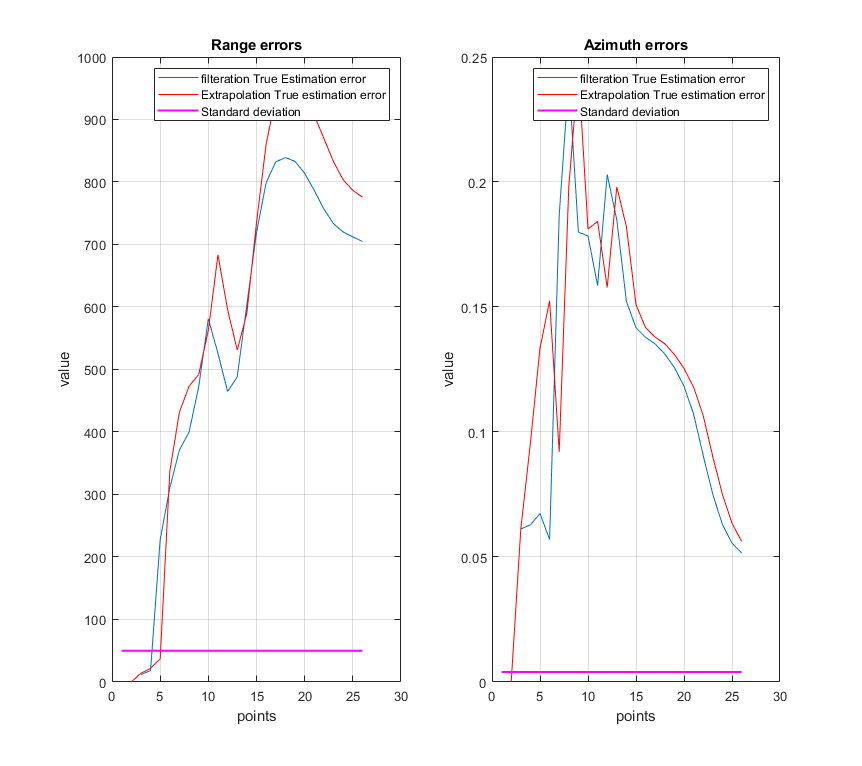


%plotting errors
figure
subplot(1,2,1)
plotErr(ErrD,ErrDE,sigma_d*ones(1,N),'Range')
subplot(1,2,2)
plotErr(Errbeta,ErrbetaE,sigma_beta*ones(1,N),'Azimuth')